clear all
close all
clc

Primero limpiamos la consola y la pantalla

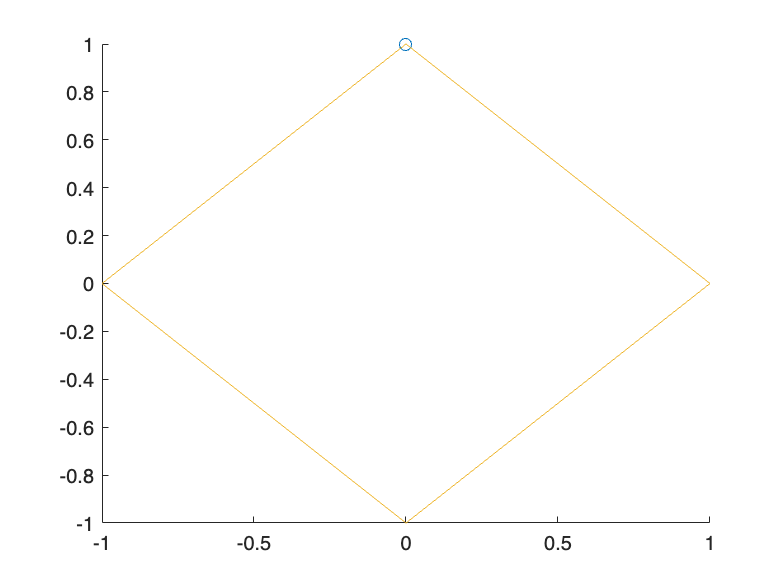

% Rombo
x1 = [0 1 0 -1 0];
y1 = [1 0 -1 0 1];
figure(1)
comet(x1, y1)

Para el rombo se definen cinco puntos específicos que forman un rombo al conectarse en secuencia. Los puntos son (0,1)(0,1), (1,0)(1,0), (0,−1)(0,−1), (−1,0)(−1,0) y nuevamente (0,1)(0,1) para cerrar la figura.

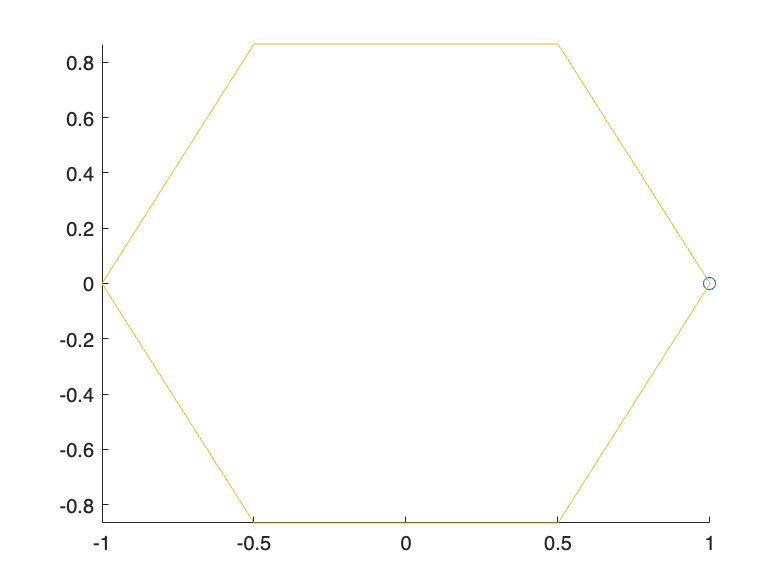

% Hexágono
t_hex = linspace(0, 2*pi, 7);
x_hex = cos(t_hex);
y_hex = sin(t_hex);
figure(2)
comet(x_hex, y_hex)

En el hexagono se calculan siete puntos equidistantes alrededor de un círculo unitario usando cos (θ)cos(θ) y sin (θ)sin(θ), donde θθ varía de 0 a 2π2π en seis divisiones, asegurando que el último punto coincide con el primero para cerrar la figura.

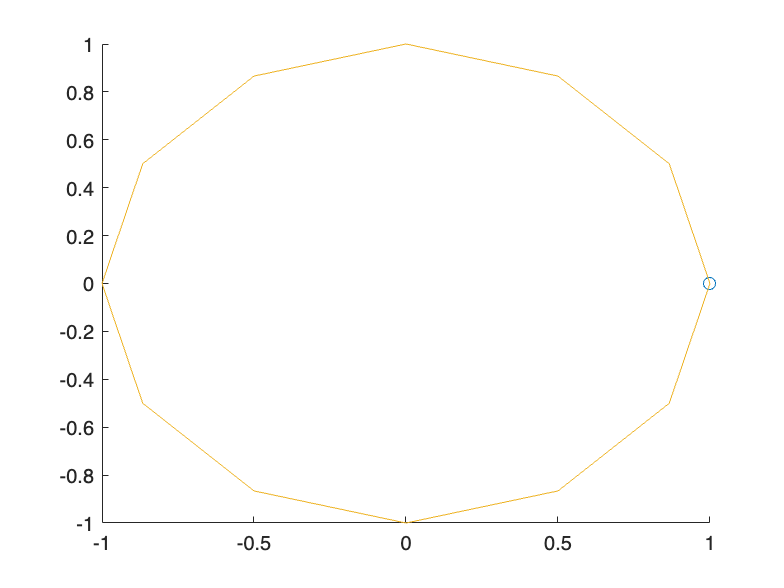

% Dodecágono (12 lados)
t_dodec = linspace(0, 2*pi, 13);
x_dodec = cos(t_dodec);
y_dodec = sin(t_dodec);
figure(3)
comet(x_dodec, y_dodec)

Para el dodecagono, hice algo similar al hexágono, pero con un mayor número de divisiones (12+112+1) en el intervalo 00 a 2π2π. Esto genera una figura de 12 lados conectados por segmentos de línea.

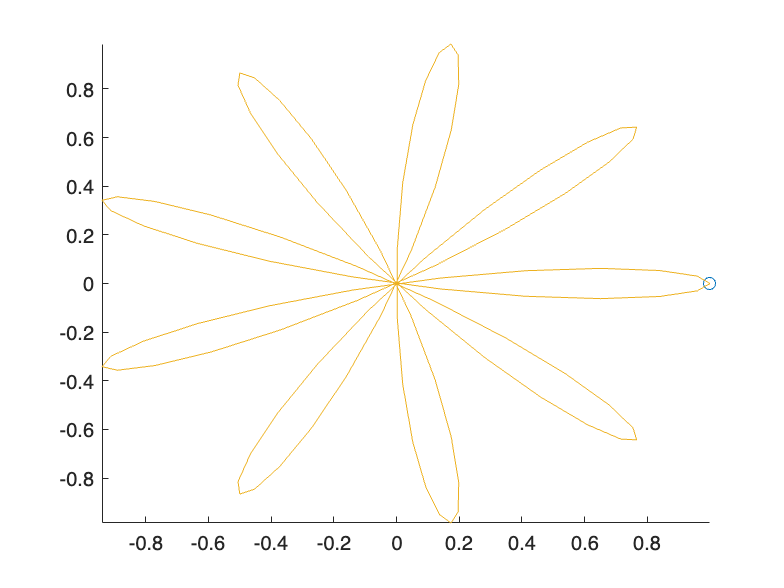

t = linspace(0, pi, 100);
k1 = 9;
x1 = cos(k1 * t) .* cos(t);
y1 = cos(k1 * t) .* sin(t);
figure(1)
comet(x1, y1)

Despues se genera una trayectoria suavizada del rombo utilizando una función trigonométrica con una frecuencia de 9. La transformación cos (9t+π/4)cos(9t+π/4) junto con cos (t)cos(t) y sin (t)sin(t) ayuda a dar la forma alargada del rombo y permite una transición continua.

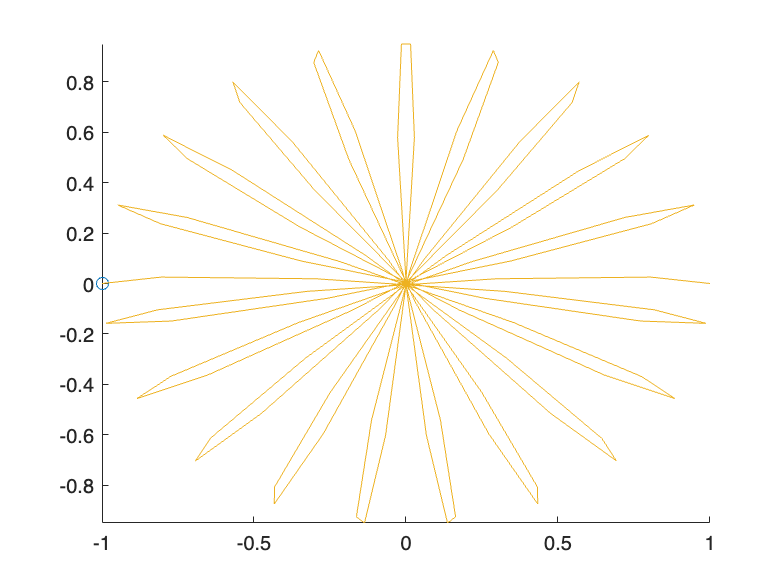

k2 = 20;
x2 = cos(k2 * t) .* cos(t);
y2 = cos(k2 * t) .* sin(t);
figure(2)
comet(x2, y2)

En esta figura se usa una función trigonométrica con una frecuencia de 20 para crear una aproximación continua del hexágono. Los términos cos (20t)cos(20t) aplicados a cos (t)cos(t) y sin (t)sin(t) generan la oscilación necesaria para dar forma a la figura.

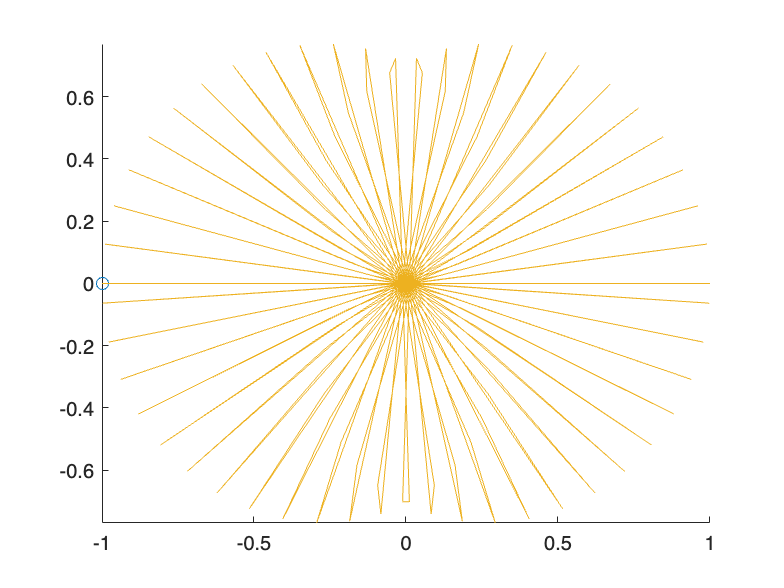

k3 = 50; 
x3 = cos(k3 * t) .* cos(t);
y3 = cos(k3 * t) .* sin(t);
figure(3)
comet(x3, y3)

Se implementa una frecuencia de 50 en las funciones trigonométricas. Esta parametrización ayuda a mantener la continuidad en el trazo y a visualizar la figura de manera fluida.